num_armax = [0.755];
den_armax = [1 13.87 34.91];
tf_t = tf( num_armax, den_armax)

tf_t =
 
          0.755
  ---------------------
  s^2 + 13.87 s + 34.91
 
Continuous-time transfer function.
Model Properties


pole(tf_t)

ans =   -10.5660
   -3.3040


tf_t_closed = feedback( tf_t, 1)

tf_t_closed =
 
          0.755
  ---------------------
  s^2 + 13.87 s + 35.66
 
Continuous-time transfer function.
Model Properties


pole(tf_t_closed)

ans =   -10.4605
   -3.4095


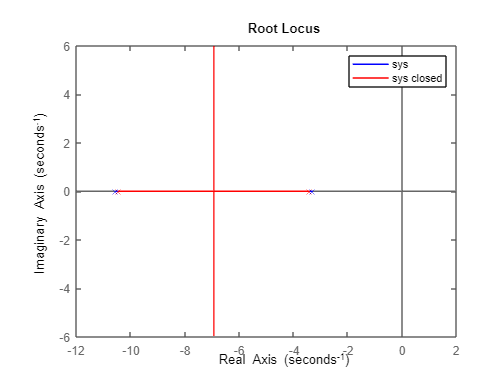

rlocus( tf_t, 'b', tf_t_closed, 'r')
hold on
legend('sys','sys closed')
hold off

[ wn, z] = damp(tf_t_closed)

wn =     3.4095
   10.4605


z =      1
     1


stepinfo(tf_t_closed)

ans = struct with fields:
         RiseTime: 0.6991
    TransientTime: 1.2631
     SettlingTime: 1.2631
      SettlingMin: 0.0191
      SettlingMax: 0.0211
        Overshoot: 0
       Undershoot: 0
             Peak: 0.0211
         PeakTime: 2.1044



num_BJ = [0.6979];
den_BJ = [1 12.23 35.01];
tf_BJ = tf( num_BJ, den_BJ)

tf_BJ =
 
         0.6979
  ---------------------
  s^2 + 12.23 s + 35.01
 
Continuous-time transfer function.
Model Properties


pole(tf_BJ)

ans =    -7.6588
   -4.5712


tf_BJ_closed = feedback( tf_BJ, 1)

tf_BJ_closed =
 
         0.6979
  ---------------------
  s^2 + 12.23 s + 35.71
 
Continuous-time transfer function.
Model Properties


pole(tf_BJ_closed)

ans =    -7.4132
   -4.8168


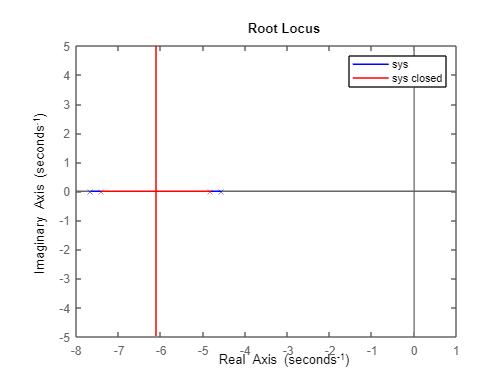

rlocus(tf_BJ);rlocus( tf_BJ, 'b', tf_BJ_closed, 'r')
hold on
legend('sys','sys closed')
hold off

K_controller = 237.98;
num_controller = [1 14.6];
den_controller = [1 9.804];

G_c = tf( K_controller*num_controller, den_controller)

G_c =
 
  238 s + 3475
  ------------
   s + 9.804
 
Continuous-time transfer function.
Model Properties


Gc_tf = series( G_c, tf_t)

Gc_tf =
 
           179.7 s + 2623
  ---------------------------------
  s^3 + 23.67 s^2 + 170.9 s + 342.3
 
Continuous-time transfer function.
Model Properties


full_tf = feedback(Gc_tf, 1)

full_tf =
 
           179.7 s + 2623
  --------------------------------
  s^3 + 23.67 s^2 + 350.6 s + 2966
 
Continuous-time transfer function.
Model Properties


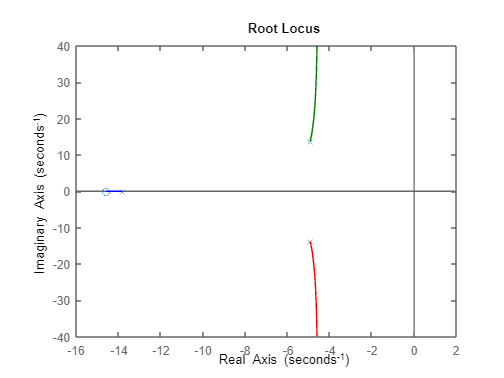

rlocus(full_tf)

pole(full_tf)

ans =  -13.8301 + 0.0000i
  -4.9219 +13.7913i
  -4.9219 -13.7913i


stepinfo(full_tf)

ans = struct with fields:
         RiseTime: 0.0962
    TransientTime: 0.7571
     SettlingTime: 0.7571
      SettlingMin: 0.7944
      SettlingMax: 1.1592
        Overshoot: 31.0462
       Undershoot: 0
             Peak: 1.1592
         PeakTime: 0.2339


[ wn, z] = damp(full_tf)

wn =    13.8301
   14.6432
   14.6432


z =     1.0000
    0.3361
    0.3361


Ts = 0.01;%%sampling period making a sampling rate of 100Hz
c2d( G_c, Ts,"zoh")

ans =
 
  238 z - 204.9
  -------------
   z - 0.9066
 
Sample time: 0.01 seconds
Discrete-time transfer function.
Model Properties
